# Measure Frequency Response of an Audio Device

The frequency response (FR) is an important tool for characterizing the fidelity of an audio device or component.

This example requires an audio device capable of recording and playing audio and an appropriate audio driver. To learn more about how the example records and plays audio data, see [`audioDeviceReader`](docid:audio_ref#bu1_i72-1) and [`audioDeviceWriter`](docid:audio_ref#bu5y2a_-1).

## Description of FR Measurement Techniques

An FR measurement compares the output levels of an audio device to known input levels. A basic FR measurement consists of two or three test tones: mid, high, and low.

In this example you perform an audible range FR measurement by sweeping a sine wave from the lowest frequency in the range to the highest. A flat response indicates an audio device that responds equally to all frequencies.

## Setup Experiment

In this example, you measure the FR by playing an audio signal through `audioDeviceWriter` and then recording the signal through `audioDeviceReader`. A loopback cable is used to physically connect the audio-out port of the sound card to its audio-in port.

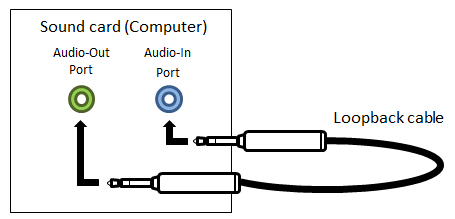

## Audio Device Reader and Writer

To start, use the `audioDeviceReader` System object™ and `audioDeviceWriter` System object to connect to the audio device. This example uses a Focusrite Scarlett 2i2 audio device with a 48 kHz sampling rate.

sampleRate = 44e3;

% Set the input (recording) device
inputDevice = "Primary Sound Capture Driver"; 

% Set the output (playback) device. 
% Try "Default" or the specific USB audio device if you are using the lab's USB dongle.
outputDevice = "Default"; 

aDR = audioDeviceReader(Device=inputDevice);
aDW = audioDeviceWriter(Device=outputDevice);

## Test Signal

The test signal is a sine wave with 1024 samples per frame and an initial frequency of 0 Hz. The frequency is increased in 50 Hz increments to sweep the audible range.

samplesPerFrame = 1024;
sineSource  = audioOscillator( ...
      Frequency=0, ...
      SignalType="sine", ...
      SampleRate=sampleRate, ...
      SamplesPerFrame=samplesPerFrame);

## Spectrum Analyzer

Use the `spectrumAnalyzer` to visualize the FR of your audio I/O system. 20 averages of the spectrum estimate are used throughout the experiment and the resolution bandwidth is set to 50 Hz. The sampling frequency is set to 48 kHz.

RBW = 100;
Navg = 10;

scope = spectrumAnalyzer( ...
      SampleRate=sampleRate, ...
      RBWSource="property",RBW=RBW, ...
      AveragingMethod="exponential", ...
      ForgettingFactor=0, ...
      FrequencySpan="start-and-stop-frequencies",...
      StartFrequency=0, ...
      StopFrequency=sampleRate/2, ...
      PlotAsTwoSidedSpectrum=false, ...
      FrequencyScale="linear", ...
      PlotMaxHoldTrace=true, ...
      ShowLegend=true, ...
      YLimits=[-110 20],...
      YLabel="Power", ...
      Title="Audio Device Frequency Response");

## Frequency Response Measurement Loop

To avoid the impact of setup time on the FR measurement, prerun your audio loop for 5 seconds.

Once the actual FR measurement starts, sweep the test signal through the audible frequency range. Use the spectrum analyzer to visualize the FR.

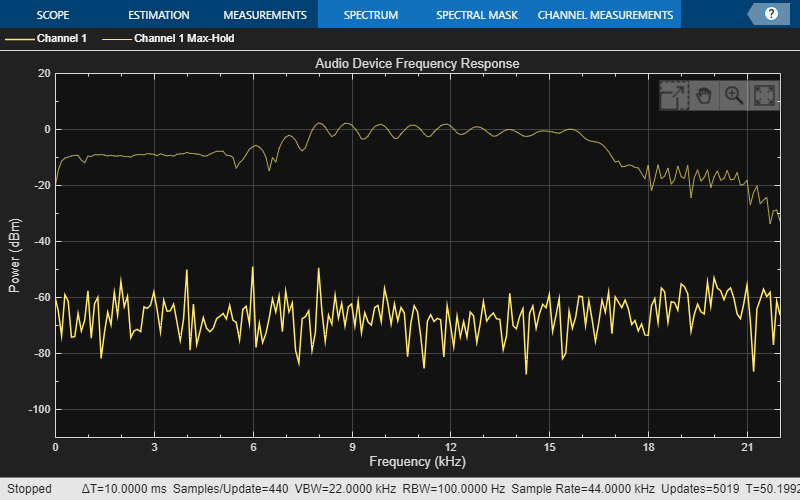

tic
while toc < 5
    x = sineSource();
    aDW(x);
    y = aDR();
    scope(y);    
end
        
count = 1;
readerDrops = 0;
writerDrops = 0;

while true
    if count == Navg
        newFreq = sineSource.Frequency + RBW;
        if newFreq > sampleRate/2
            break
        end
        sineSource.Frequency = newFreq;
        count = 1;
    end
    x = sineSource();
    writerUnderruns = aDW(x);
    [y,readerOverruns] = aDR();
    readerDrops = readerDrops + readerOverruns;        
    writerDrops = writerDrops + writerUnderruns; 
    scope(y);        
    count = count + 1;
end

release(aDR)
release(aDW)
release(scope)

## Frequency Response Measurement Results

The spectrum analyzer shows two plots. The first plot is the spectrum estimate of the last recorded data. The second plot is the maximum power the spectrum analyzer computed for each frequency bin, as the sine wave swept over the spectrum. To get the maximum hold plot data and the frequency vector, you can use the object function `getSpectrumData` and plot the maximum hold trace only.

data = getSpectrumData(scope);
freqVector = data.FrequencyVector{1};
freqResponse = data.MaxHoldTrace{1};

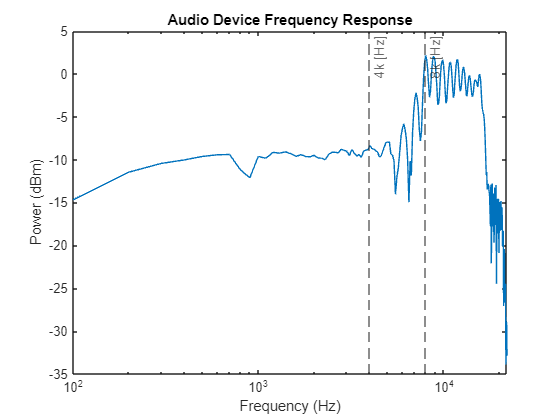

clf;
semilogx(freqVector,freqResponse);
xlabel("Frequency (Hz)");
ylabel("Power (dBm)");
xline(4e3,"--","4k [Hz]");
xline(8e3,"--","8k [Hz]")
title("Audio Device Frequency Response");

The frequency response plot indicates that the audio device tested in this example has a flat frequency response in the audible range.

*Copyright 2017-2022 The MathWorks, Inc.*

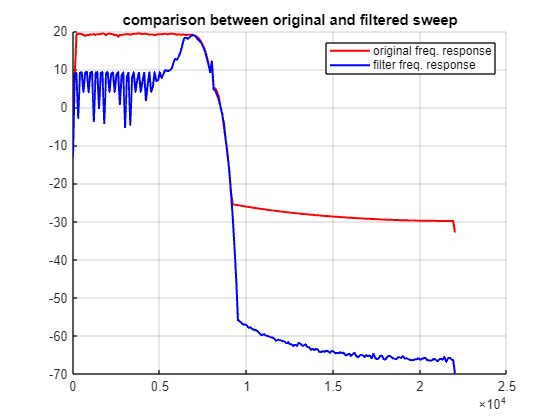

% 1. Open the saved figures (invisibly so they don't pop up and clutter your screen)
fig1 = openfig("figures\audio_freq_response_1_10.fig", 'invisible');
fig2 = openfig("figures\audio_freq_response_3_4.fig", 'invisible');


% 2. Find the axes within those figures
ax1 = findobj(fig1, 'Type', 'axes');
ax2 = findobj(fig2, 'Type', 'axes');

% 3. Extract the actual line data
lines1 = findobj(ax1, 'Type', 'Line');
lines2 = findobj(ax2, 'Type', 'Line');

% 4. Create a brand new figure
figure('Name', 'Combined Overlay');
new_ax = axes; 
hold on; grid on;

% 5. Copy the lines and SAVE their new handles
new_line1 = copyobj(lines1, new_ax);
new_line2 = copyobj(lines2, new_ax);

% 6. CHANGE THE COLORS HERE
% You can use standard letter codes ('r', 'b', 'g', 'k', 'm', 'c', 'y')
new_line1.Color = 'r'; % Makes the first line Red
new_line2.Color = 'b'; % Makes the second line Blue

% (Optional) You can also make them thicker so they are easier to see
new_line1.LineWidth = 1.5;
new_line2.LineWidth = 1.5;

% 7. Add a legend
title("comparison between original and filtered sweep")
legend('original freq. response', 'filter freq. response');


% 8. Close the original hidden figures
close(fig1);
close(fig2);